Loads and processes data (run everything from playground)

% % fluo, MeanAP
% set1 = load('../dat/3400b_7dT/inference_traces_3400b_7dT_dT7.mat', 'trace_struct_final');
% %set1 = load('../dat/1900b_7dT_alt2/inference_traces_1500b_7dT_alt2_dT7.mat', 'trace_struct_final');
% set1 = set1.trace_struct_final;
% trace_struct1 = struct;
% idx = 1;
% for i = 1:length(set1)
%     if length(set1(i).cp_frames) > 30
%         trace_struct1(idx).fluo = set1(i).fluo_interp;
%         trace_struct1(idx).ap = (.40 - set1(i).MeanAP) * 100;
%         idx = idx + 1;
%     end
% end
% % fluo_interp, MeanAP
% set2 = load('../dat/2650b_7dT_alt/inference_traces_2250b_7dT_alt_dT7.mat', 'trace_struct_final');
% %set2 = load('../dat/1900b_7dT_set2/inference_traces_1500b_7dT_set2_dT7.mat', 'trace_struct_final');
% set2 = set2.trace_struct_final;
% trace_struct2 = struct;
% idx = 1;
% for i = 1:length(set2)
%     if length(set2(i).fluo_interp) > 30 && ...
%             length(set2(i).cp_frames) / ...
%             length(set2(i).all_frames) > 0
%         trace_struct2(idx).fluo = set2(i).fluo_interp;
%         trace_struct2(idx).ap = set2(i).MeanAP;
%         idx = idx + 1;
%     end
% end

load('../dat/compiled_data/1900compiled.mat');
load('../dat/compiled_data/2650compiled.mat');
load('../dat/compiled_data/3400compiled.mat');
load('../dat/compiled_data/1900compiled13.mat');
load('../dat/compiled_data/2650compiled13.mat');
load('../dat/compiled_data/3400compiled13.mat');

Compiles data sets for nc14 (enforcing constraints on trace length and minimum number of points registered)

% compiles 1.9kb traces

all1900 = load('../dat/1.9kb_data/inference_traces_1.9kb_data_dT7.5.mat', 'trace_struct_final');
all1900 = all1900.trace_struct_final;
final1900 = struct;
idx = 1;
for entry = all1900
    if length(entry.cp_frames) > 30
        final1900(idx).fluo = entry.fluo_interp;
        final1900(idx).ap = entry.MeanAP;
        final1900(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/1900compiled.mat', 'final1900');

all2650 = load('../dat/2.65kb_data/inference_traces_2.65kb_data_dT7.5.mat', 'trace_struct_final');
all2650 = all2650.trace_struct_final;
final2650 = struct;
idx = 1;
for entry = all2650
    if length(entry.cp_frames) > 30
        final2650(idx).fluo = entry.fluo_interp;
        final2650(idx).ap = entry.MeanAP;
        final2650(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/2650compiled.mat', 'final2650');

all3400 = load('../dat/3.4kb_data/inference_traces_3.4kb_data_dT7.5.mat', 'trace_struct_final');
all3400 = all3400.trace_struct_final;
final3400 = struct;
idx = 1;
for entry = all3400
    if length(entry.cp_frames) > 30
        final3400(idx).fluo = entry.fluo_interp;
        final3400(idx).ap = entry.MeanAP;
        final3400(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/3400compiled.mat', 'final3400');

Compiles datasets for nc13

% compiles 1.9kb traces

all1900 = load('../dat/1.9kb_data_nc13/inference_traces_1.9kb_data_nc13_dT7.mat', 'trace_struct_final');
all1900 = all1900.trace_struct_final;
final1900_13 = struct;
idx = 1;
for entry = all1900
    if length(entry.cp_frames) > 30
        final1900_13(idx).fluo = entry.fluo_interp;
        final1900_13(idx).ap = entry.MeanAP;
        final1900_13(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/1900compiled13.mat', 'final1900_13');

all2650 = load('../dat/2.65kb_data_nc13/inference_traces_2.65kb_data_nc13_dT7.mat', 'trace_struct_final');
all2650 = all2650.trace_struct_final;
final2650_13 = struct;
idx = 1;
for entry = all2650
    if length(entry.cp_frames) > 30
        final2650_13(idx).fluo = entry.fluo_interp;
        final2650_13(idx).ap = entry.MeanAP;
        final2650_13(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/2650compiled13.mat', 'final2650_13');

all3400 = load('../dat/3.4kb_data_nc13/inference_traces_3.4kb_data_nc13_dT7.mat', 'trace_struct_final');
all3400 = all3400.trace_struct_final;
final3400_13 = struct;
idx = 1;
for entry = all3400
    if length(entry.cp_frames) > 30
        final3400_13(idx).fluo = entry.fluo_interp;
        final3400_13(idx).ap = entry.MeanAP;
        final3400_13(idx).perc_frames = length(entry.cp_frames) ...
            / length(entry.all_frames);
        idx = idx + 1;
    end
end

save('../dat/compiled_data/3400compiled13.mat', 'final3400_13');

Looks at random traces

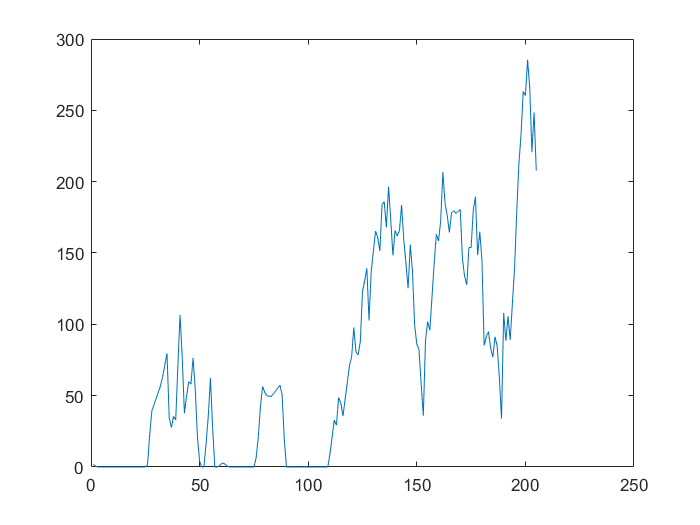

figure();
plot(final3400(49).fluo);

Compare how many in between points each of them missed

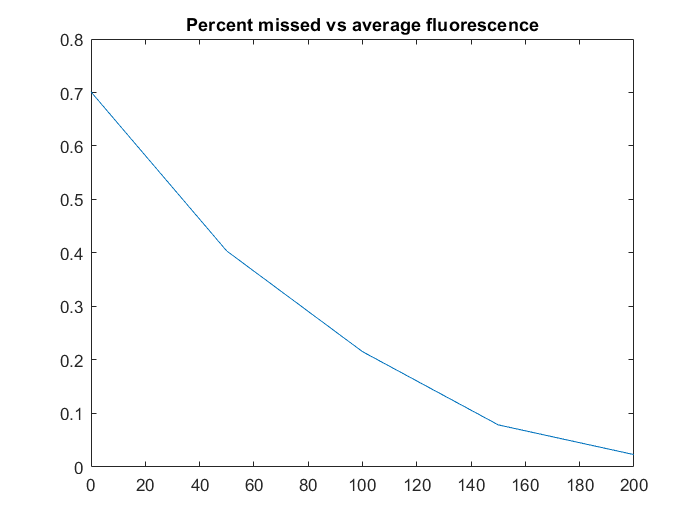

trace_struct = [final2650];
fluo2250 = 0:50:1000;
miss2250 = zeros(1, length(fluo2250));
counts2250 = zeros(1, length(fluo2250));
for i = 1:length(trace_struct)
    
    mean_val = mean(trace_struct(i).fluo);
    [val, idx] = min(abs(mean_val - fluo2250));
    miss2250(idx) = miss2250(idx) + (1-trace_struct(i).perc_frames);
    counts2250(idx) = counts2250(idx) + 1;
end
miss2250 = miss2250 ./ counts2250;

figure();
plot(fluo2250, miss2250);

title('Percent missed vs average fluorescence');

Looks at fluorescence content

fluo_distrib = []


fluo_distrib =

     []



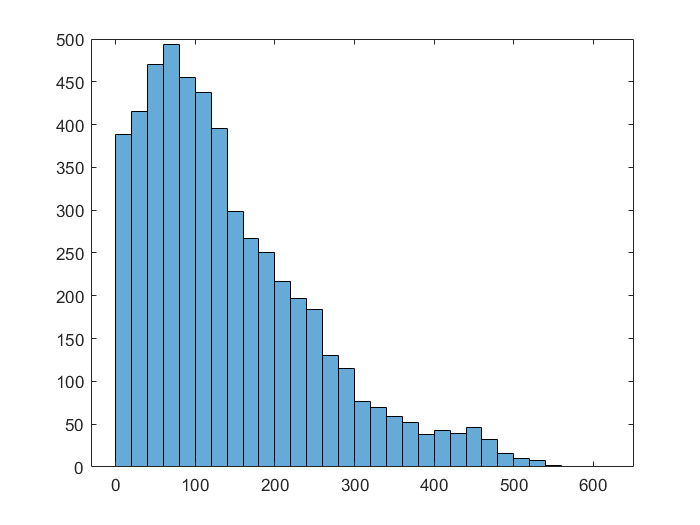

trace_struct = [final3400_13];
trace_struct = trace_struct(abs([trace_struct.ap]) < 2);
for i = 1:length(trace_struct)
    fluo_distrib = [fluo_distrib trace_struct(i).fluo];
end
thresh = 0;
fluo_distrib = fluo_distrib(fluo_distrib > thresh);
figure();
title('Fluorescnece Distribution');
histogram(fluo_distrib);

display(mean(fluo_distrib));

  143.6209



%display(length(fluo_distrib(fluo_distrib > 400)) / length(fluo_distrib));

Preps for autocorrelation and derivatives (and generates them) (run from src)

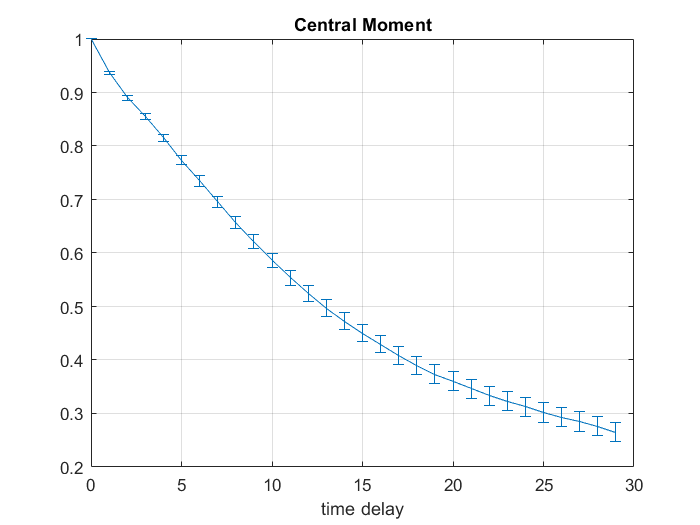

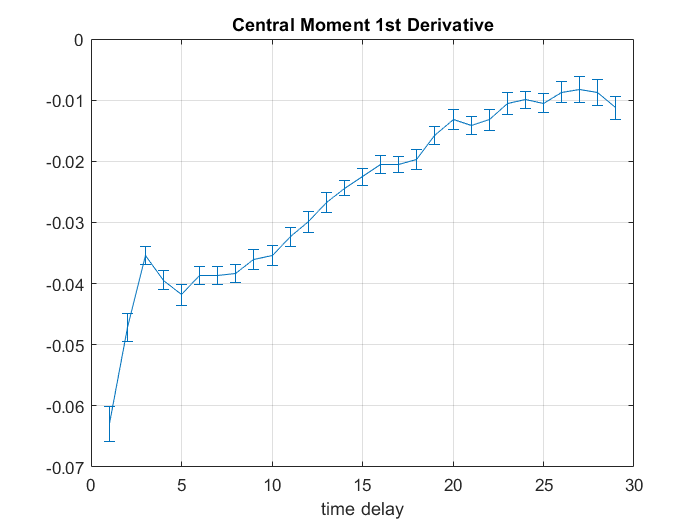

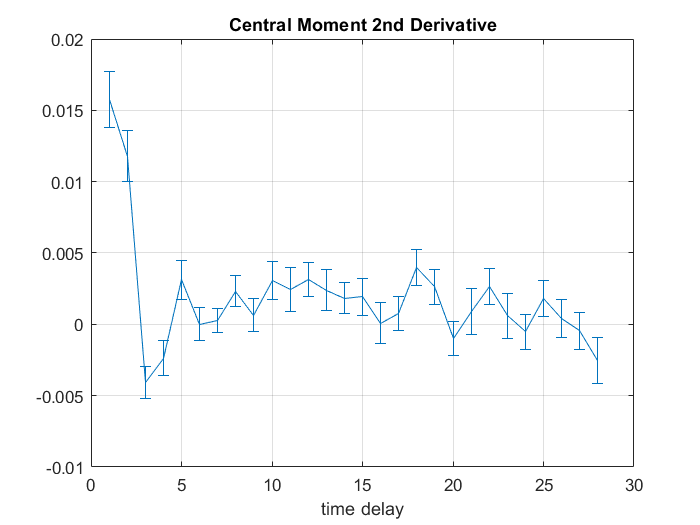

addpath('../')
to_add = [final3400];
trace_struct = [to_add(1)];
for i = 2:length(to_add)
    if length(to_add(i).fluo) > 30
        trace_struct = [trace_struct to_add(i)];
    end
end
trace_struct = trace_struct(abs([trace_struct.perc_frames]) > .2);

traces = cell(1, length(trace_struct));
for i = 1:length(traces)
    fluo = trace_struct(i).fluo;
    traces{i} = smooth(fluo,1)';
end
gen_auto_cor(traces, 0:2, true, 30, 0);

Divides traces up into 36 long fragments (making sure that none of them are more than 1/3 zero). 12 points repeat ever time.

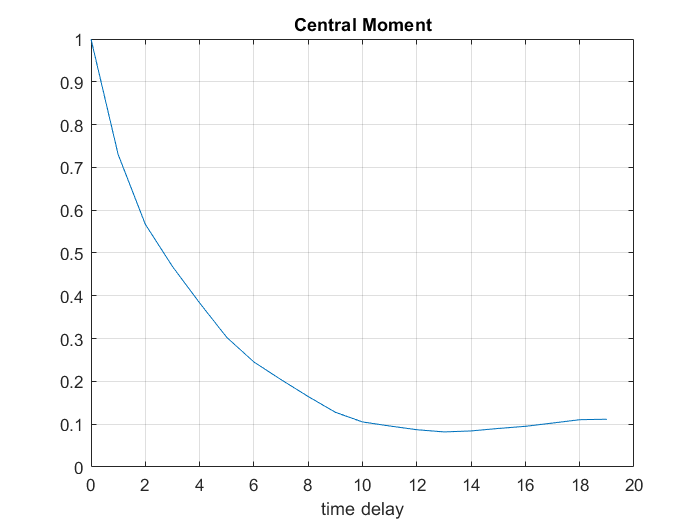

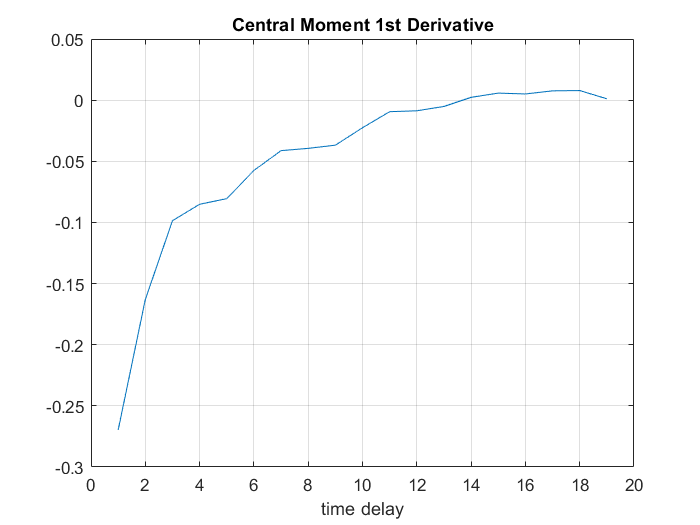

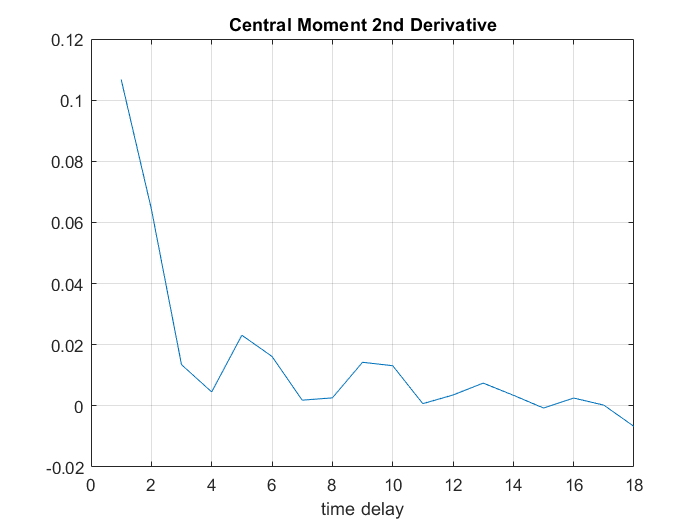

addpath('../');
trace_struct = [trace_struct1 trace_struct2];
traces = cell(1);
trace_len = 24;
num_nonzero = 22;
jump = 1;
idx = 1;
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    j = 1;
    while j + trace_len - 1 <= length(fluo)
        if nnz(fluo(j:j+trace_len-1)) > num_nonzero
            traces{idx} = fluo(j:j+trace_len-1);
            idx = idx + 1;
        end
        j = j + jump;
    end
end

gen_auto_cor(traces,0:2,false,20,0);

Downsamples traces

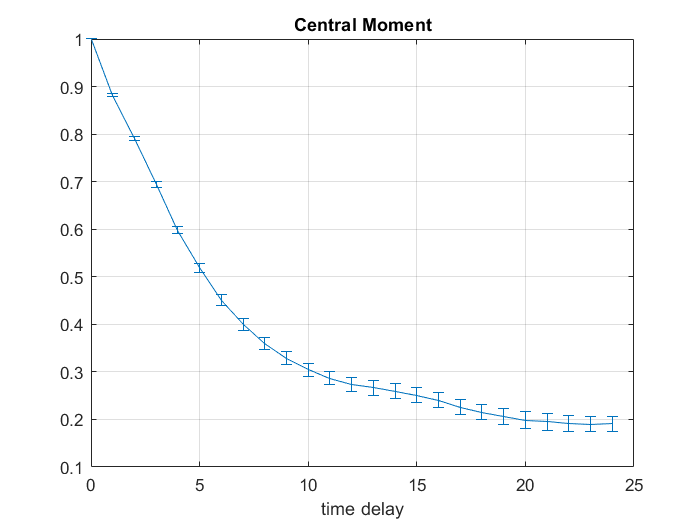

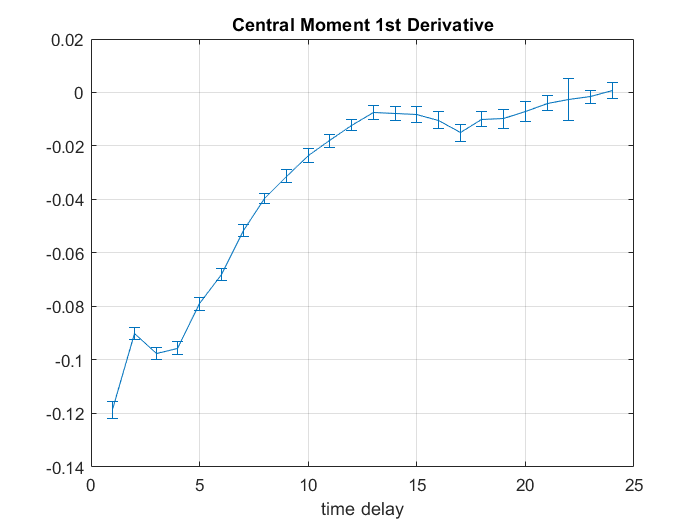

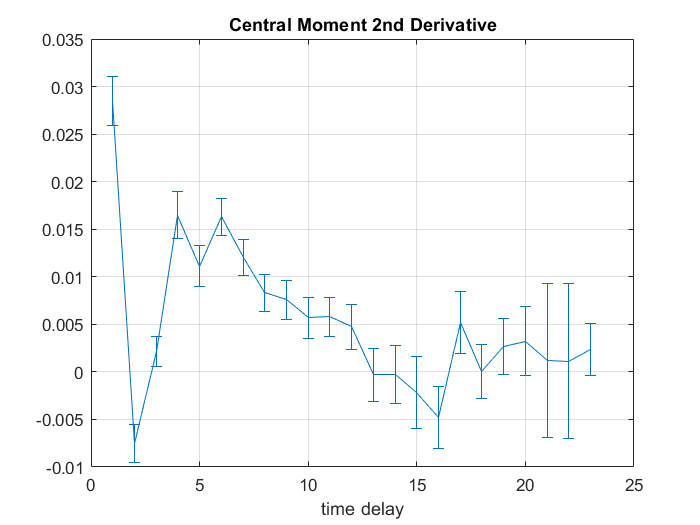

addpath('../');
trace_struct = [final2650];
traces = cell(1);
skip = 1;
idx = 1;
for i = 1:length(trace_struct)
    fluo = smooth(trace_struct(i).fluo,1)';
    for s = 1:skip + 1
        traces{idx} = fluo(skip:skip+1:end);
        idx = idx + 1;
    end
end

gen_auto_cor(traces,0:2,true,25,0);

Downsample selective traces

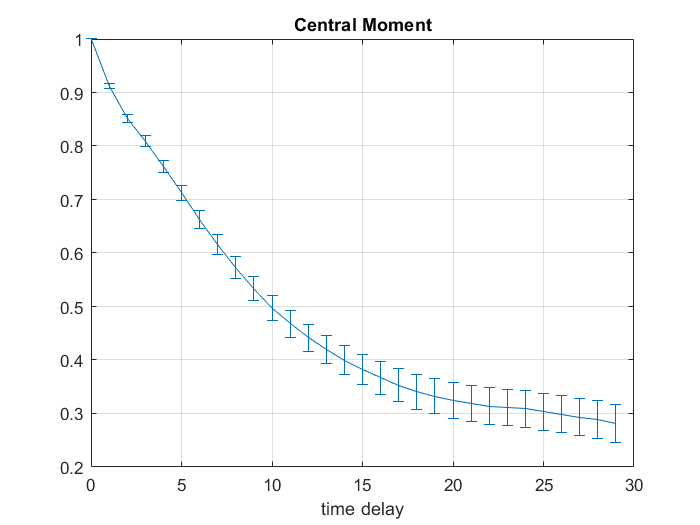

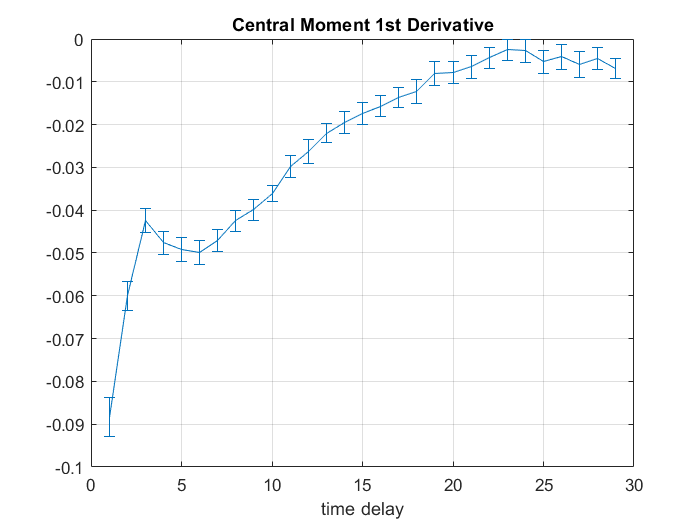

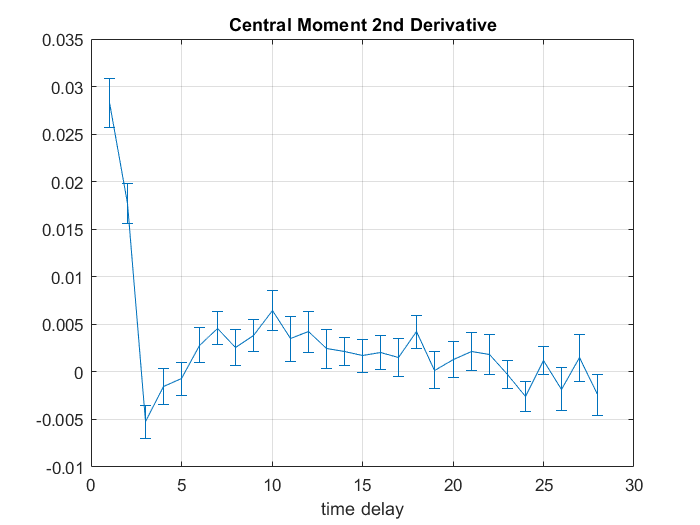

addpath('../');
trace_struct = [final2650];
traces = cell(1);
min_len = 100;
idx = 1;
thresh = 0;
thresh_h = 1000;
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    j = 1;
    start = 1;
    while j <= length(fluo)
        if fluo(j) <= thresh && fluo(j) < thresh_h
            if j - start >= min_len
                traces{idx} = fluo(start:j-1);
                idx = idx + 1;
            end
            start = j + 1;
        end
        j = j + 1;
    end
    if j - start >= min_len
        traces{idx} = fluo(start:j-1);
        idx = idx + 1;
    end
end

new_traces = cell(1);
skip = 1;
idx = 1;
for i = 1:length(traces)
    fluo = traces{i};
    for s = 1:skip + 1
        new_traces{idx} = fluo(skip:skip+1:end);
        idx = idx + 1;
    end
end

gen_auto_cor(traces,0:2,true,30,0);

Measures burst size distribution for each case (bursts must be longer than 2 points)

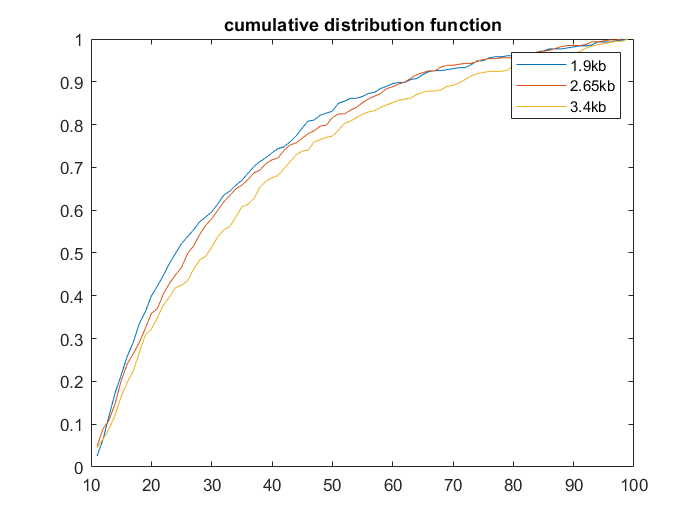

bursts1900 = [];
thresh = 10;
thresh_h = 100;
for i = 1:length(final1900)
    zeroes1900 = find(final1900(i).fluo == 0);
    bursts1900 = [bursts1900 zeroes1900(2:end) - zeroes1900(1:end-1) - 1];
end
bursts1900 = bursts1900(bursts1900 > thresh & bursts1900 < thresh_h);
bursts1900_sorted = zeros(1, max(bursts1900));
for i = 1:length(bursts1900_sorted)
    bursts1900_sorted(i) = numel(find(bursts1900 == i));
end
bursts1900_sorted = bursts1900_sorted / sum(bursts1900_sorted);
for i = 2:length(bursts1900_sorted)
    bursts1900_sorted(i) = bursts1900_sorted(i-1) + bursts1900_sorted(i);
end

bursts2650 = [];
for i = 1:length(final2650)
    zeros2650 = find(final2650(i).fluo == 0);
    bursts2650 = [bursts2650 zeros2650(2:end) - zeros2650(1:end-1) - 1];
end
bursts2650 = bursts2650(bursts2650 > thresh & bursts2650 < thresh_h);
bursts2650_sorted = zeros(1, max(bursts2650));
for i = 1:length(bursts2650_sorted)
    bursts2650_sorted(i) = numel(find(bursts2650 == i));
end
bursts2650_sorted = bursts2650_sorted / sum(bursts2650_sorted);
for i = 2:length(bursts2650_sorted)
    bursts2650_sorted(i) = bursts2650_sorted(i-1) + bursts2650_sorted(i);
end

bursts3400 = [];
for i = 1:length(final3400)
    zeros3400 = find(final3400(i).fluo == 0);
    bursts3400 = [bursts3400 zeros3400(2:end) - zeros3400(1:end-1) - 1];
end
bursts3400 = bursts3400(bursts3400 > thresh & bursts3400 < thresh_h);
bursts3400_sorted = zeros(1, max(bursts3400));
for i = 1:length(bursts3400_sorted)
    bursts3400_sorted(i) = numel(find(bursts3400 == i));
end
bursts3400_sorted = bursts3400_sorted / sum(bursts3400_sorted);
for i = 2:length(bursts3400_sorted)
    bursts3400_sorted(i) = bursts3400_sorted(i-1) + bursts3400_sorted(i);
end

figure();
plot((thresh+1):length(bursts1900_sorted), ...
    bursts1900_sorted((thresh+1):end));
hold on
plot((thresh+1):length(bursts2650_sorted), ...
    bursts2650_sorted((thresh+1):end));
hold on
plot((thresh+1):length(bursts3400_sorted), ...
    bursts3400_sorted((thresh+1):end));
legend('1.9kb', '2.65kb', '3.4kb');
title('cumulative distribution function')

mean1900 = mean(bursts1900)

mean1900 = 31.8176

mean2650 = mean(bursts2650)

mean2650 = 32.8096

mean3400 = mean(bursts3400)

mean3400 = 35.8081

Look at histogram of point to point fluorescence change

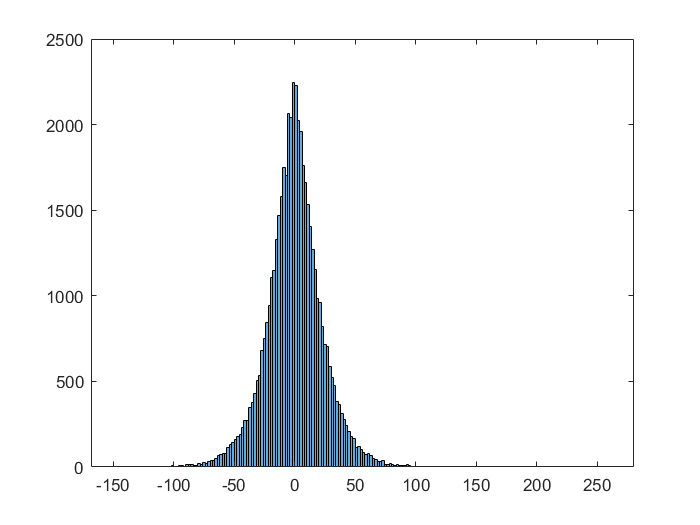

trace_struct = [final2650];
changes = [];
thresh = 0;
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    for j = 2:length(fluo)
        if fluo(j) > thresh && fluo(j-1) > thresh
            changes = [changes fluo(j) - fluo(j-1)];
        end
    end
end
changes = changes(abs(changes) > 0);
histogram(changes);

Is there bottlenecking? Is it a Poisson process? Look at sustained increase and decrease and see the pattern.

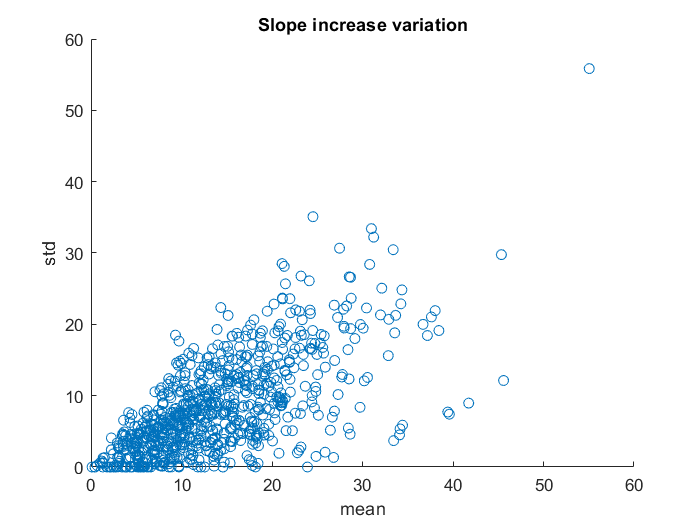

% first identify monotonic increases longer than threshhold
thresh = 5;
cut = 1;
trace_struct = [final3400];
pos_means = [];
pos_stds = [];
neg_means = [];
neg_stds = [];
for i = 1:length(trace_struct)
    fluo = trace_struct(i).fluo;
    diff = fluo(2:end) - fluo(1:end-1);
    dir = diff(1) > 0;
    sus = 1;
    for j = 2:length(diff)
        if diff(j) > 0 == dir
            sus = sus + 1;
        else
            if sus >= thresh
                new_mean = mean(diff(j-sus+cut:j-1-cut));   
                new_std = std(diff(j-sus+cut:j-1-cut));
                if dir
                    pos_means = [pos_means new_mean];
                    pos_stds = [pos_stds new_std];
                else
                    neg_means = [neg_means -new_mean];
                    neg_stds = [neg_stds new_std];
                end
            end
            sus = 1;
            dir = diff(j) > 0;
        end
    end
    if sus >= thresh
        new_mean = mean(diff(end-sus+cut:end-cut));   
        new_std = std(diff(end-sus+cut:end-cut));
        if dir
            pos_means = [pos_means new_mean];
            pos_stds = [pos_stds new_std];
        else
            neg_means = [neg_means -new_mean];
            neg_stds = [neg_stds new_std];
        end
    end
end
figure();
scatter(pos_means, pos_stds);
title('Slope increase variation');
xlabel('mean');
ylabel('std');

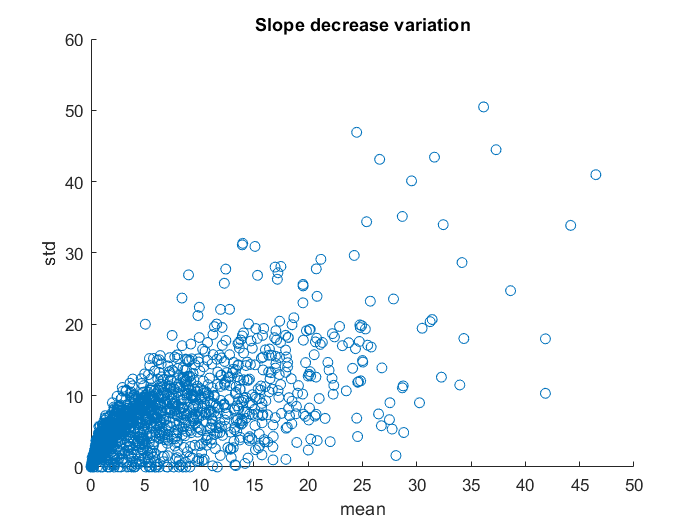


figure();
scatter(neg_means, neg_stds);
title('Slope decrease variation');
xlabel('mean');
ylabel('std');

histogram of maximum fluorescence in every trace longer than min_len time points

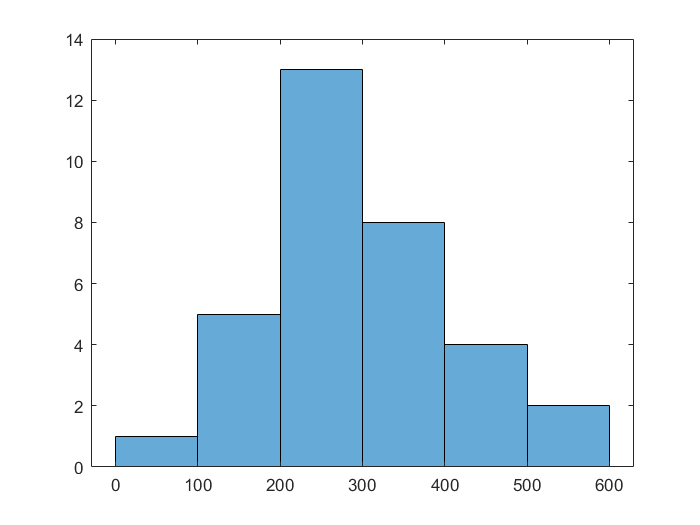

trace_struct = [final3400_13];
min_len = 50;

max_vals = [];
for i = 1:length(trace_struct)
    if length(trace_struct(i).fluo) > min_len && ...
            abs(trace_struct(i).ap) < 1
        max_vals = [max_vals max(trace_struct(i).fluo)];
    end
end
figure();
histogram(max_vals);

mean_max_val = mean(max_vals)

mean_max_val = 292.3680

std_max_val = std(max_vals)

std_max_val = 114.0160